% Load toy dataset
load toy.dat
X = [ones(10, 1), toy(:, 1:2)] % first two cols of toy.dat

X =    1.000000000000000   2.000000000000000   3.000000000000000
   1.000000000000000   3.000000000000000   2.000000000000000
   1.000000000000000   3.000000000000000   6.000000000000000
   1.000000000000000   5.500000000000000   4.500000000000000
   1.000000000000000   5.000000000000000   3.000000000000000
   1.000000000000000   7.000000000000000   4.000000000000000
   1.000000000000000   5.000000000000000   6.000000000000000
   1.000000000000000   8.000000000000000   6.000000000000000
   1.000000000000000   9.500000000000000   5.000000000000000
   1.000000000000000   9.000000000000000   7.000000000000000


t = toy(:, 3) % just keep third column

t =      0
     0
     0
     0
     0
     1
     1
     1
     1
     1


[N, ~] = size(X)

N =     10


toy

toy =    2.000000000000000   3.000000000000000                   0
   3.000000000000000   2.000000000000000                   0
   3.000000000000000   6.000000000000000                   0
   5.500000000000000   4.500000000000000                   0
   5.000000000000000   3.000000000000000                   0
   7.000000000000000   4.000000000000000   1.000000000000000
   5.000000000000000   6.000000000000000   1.000000000000000
   8.000000000000000   6.000000000000000   1.000000000000000
   9.500000000000000   5.000000000000000   1.000000000000000
   9.000000000000000   7.000000000000000   1.000000000000000


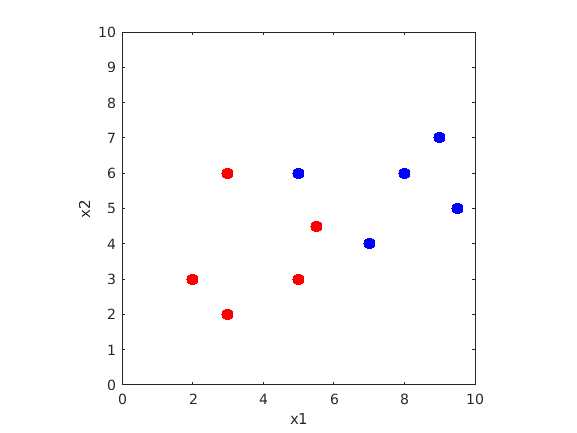

% Plot the data
figure(1); clf
plot(X(1:5, 2), X(1:5, 3), 'r.', 'MarkerSize', 30); 
hold on
plot(X(6:10, 2), X(6:10, 3), 'b.', 'MarkerSize', 30);
xlim([0 10])
ylim([0, 10]); 
axis square
xlabel('x1');
ylabel('x2');

ws = singleNeuronGradientDescent(X, t, 0.01)

ws =  -30.716395430710858
   3.004054780519867
   2.925345825593826


wb = singleNeuronBayesianGradientDescent(X, t, 0.01, 0.01)

wb =  -10.676245247482028
   1.228359829694866
   0.841653977432793


wb =  -10.676244848900975
   1.228359794181688
   0.841653935337307


% Plotting the results: the learned function
figure(1); hold on

learnedY = @(X) sigmoid(X * wb)

learnedY = function_handle with value:
    @(X)sigmoid(X*wb)


x1 = linspace(0, N)

x1 =                    0   0.101010101010101   0.202020202020202   0.303030303030303   0.404040404040404   0.505050505050505   0.606060606060606   0.707070707070707   0.808080808080808   0.909090909090909   1.010101010101010   1.111111111111111   1.212121212121212   1.313131313131313   1.414141414141414   1.515151515151515   1.616161616161616   1.717171717171717   1.818181818181818   1.919191919191919   2.020202020202020   2.121212121212121   2.222222222222222   2.323232323232323   2.424242424242424   2.525252525252525   2.626262626262626   2.727272727272727   2.828282828282828   2.929292929292930   3.030303030303030   3.131313131313131   3.232323232323232   3.333333333333333   3.434343434343434   3.535353535353535   3.636363636363636   3.737373737373737   3.838383838383838   3.939393939393939   4.040404040404041   4.141414141414141   4.242424242424242   4.343434343434343   4.444444444444445   4.545454545454546   4.646464646464646   4.747474747474747   4.848484848484849   4.9494949494

x2 = x1; 

[x1 x2] = meshgrid(x1, x2) % places them as two blocks columnwise

x1 =                    0   0.101010101010101   0.202020202020202   0.303030303030303   0.404040404040404   0.505050505050505   0.606060606060606   0.707070707070707   0.808080808080808   0.909090909090909   1.010101010101010   1.111111111111111   1.212121212121212   1.313131313131313   1.414141414141414   1.515151515151515   1.616161616161616   1.717171717171717   1.818181818181818   1.919191919191919   2.020202020202020   2.121212121212121   2.222222222222222   2.323232323232323   2.424242424242424   2.525252525252525   2.626262626262626   2.727272727272727   2.828282828282828   2.929292929292930   3.030303030303030   3.131313131313131   3.232323232323232   3.333333333333333   3.434343434343434   3.535353535353535   3.636363636363636   3.737373737373737   3.838383838383838   3.939393939393939   4.040404040404041   4.141414141414141   4.242424242424242   4.343434343434343   4.444444444444445   4.545454545454546   4.646464646464646   4.747474747474747   4.848484848484849   4.9494949494

x2 =                    0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0               

% x2 seems to be a transpose of x1

% Put ones on first column, x1 values on second col
% and x2 values on third column
% Gives 1000 x 3 matrix
argX = [ones(10000, 1),  x1(:), x2(:)] 

argX =    1.000000000000000                   0                   0
   1.000000000000000                   0   0.101010101010101
   1.000000000000000                   0   0.202020202020202
   1.000000000000000                   0   0.303030303030303
   1.000000000000000                   0   0.404040404040404
   1.000000000000000                   0   0.505050505050505
   1.000000000000000                   0   0.606060606060606
   1.000000000000000                   0   0.707070707070707
   1.000000000000000                   0   0.808080808080808
   1.000000000000000                   0   0.909090909090909
   1.000000000000000                   0   1.010101010101010
   1.000000000000000                   0   1.111111111111111
   1.000000000000000                   0   1.212121212121212
   1.000000000000000                   0   1.313131313131313
   1.000000000000000                   0   1.414141414141414
   1.000000000000000                   0   1.515151515151515
   1.000000000000


% Then reshape the 1000 x 3 matrix to be 100 x 100
% while applying the learned function
learnedY_cont = reshape(learnedY(argX), 100, 100)

learnedY_cont =    0.000023086365931   0.000026136058813   0.000029588602082   0.000033497207064   0.000037922112664   0.000042931513231   0.000048602608851   0.000055022794206   0.000062291004252   0.000070519237365   0.000079834279330   0.000090379654566   0.000102317834505   0.000115832736893   0.000131132554231   0.000148452954542   0.000168060703289   0.000190257761586   0.000215385923031   0.000243832059529   0.000276034055558   0.000312487520533   0.000353753380448   0.000400466462817   0.000453345203481   0.000513202620017   0.000580958714691   0.000657654490142   0.000744467783650   0.000842731150988   0.000953952058793   0.001079835675325   0.001222310583526   0.001383557777726   0.001566043346198   0.001772555286117   0.002006244945311   0.002270673636238   0.002569865021544   0.002908363926658   0.003291302292123   0.003724473035293   0.004214412645487   0.004768493385772   0.005395026014391   0.006103373964192   0.006904079922428   0.007809005727339   0.008831486430472   0

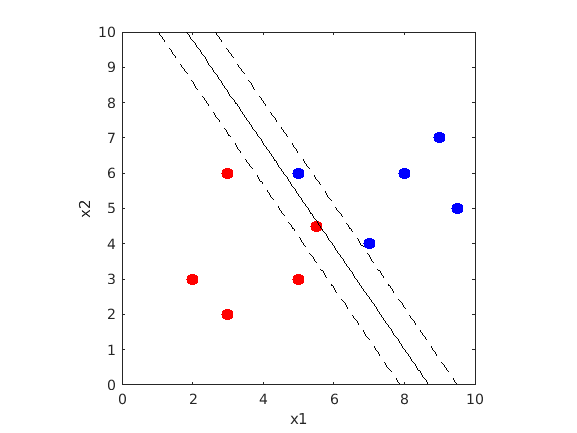

contour(x1, x2, learnedY_cont, [0.27, 0.73], '--k'); 
hold on
contour(x1, x2, learnedY_cont, [0.5, 0.5], 'k')

learnedY_cont